%compare beam squint compensation between different method
clc;
clear all;
close all;
%g0 = 0.6;

%% system parameters
Sysparam = struct();

Sysparam.Nt = 512;
MSet = divisors(Sysparam.Nt);
indices = find(MSet > 1);
MSet = MSet(indices);
Sysparam.Nr = 4;
Sysparam.Ns = 4;
Sysparam.fc = 3*1e11;%carrier frequency 
Sysparam.f = 3*1e10; %bandwidth 
Sysparam.K = 129;  %number of sub-carriers
Sysparam.L = 1 ; % number of paths equals to number of RF chains
%Sysparam.Q = 16; % number of fixed TTD element 
%% Sub-carrier frequencies
for k =1:Sysparam.K 
    Sysparam.F(k,1) = Sysparam.fc +(Sysparam.f/Sysparam.K)*(k-1-(Sysparam.K-1)/2); % sub-carrier frequency
end 
% relative frequencies
Sysparam.xi = Sysparam.F/Sysparam.fc; 

%% simulation parameters
Simparam = struct();
Nloop = 50;
Simparam.psi = pi*rand(Sysparam.L,1)-0.5*pi; %AoA;
Simparam.P = -20:5:15;% transmit power in dB
Simparam.Rho = 10.^(Simparam.P/10); %transmit power
Simparam.Niter = 50; %channel realizations
Simparam.phi = 0.2951*pi*ones(Sysparam.L,1);%AoD;
SpatialDirection = sin(Simparam.phi);
%%

%Generate wideband channel
H = WidebandChannel(Sysparam,Simparam);

for i = 1:length(MSet)
Sysparam.M = MSet(i); %number of TTDs for each RF chain
Sysparam.Q = MSet(i);
Sysparam.N = Sysparam.Nt/Sysparam.M; %number of PSs for each TTD     
Time(i) = sin(Simparam.phi)*((2*MSet(i)-1)*Sysparam.Nt-MSet(i))/(4*MSet(i)*Sysparam.fc);
Sysparam.tmax = Time(i);
Sysparam.T = Sysparam.tmax*(0:1:Sysparam.Q-1)/(Sysparam.Q-1);
[G1,G2k,x2,t2] = fixPSdesignTTD(Sysparam,Simparam); %Tan design
[PS,TTD,x,t] = jointPSandTTD(Sysparam, Simparam); % joint delay and phase precoding
[S,F2k,D,~] = DynamicSubarray(Sysparam,Simparam,H,Nloop); %Dynamic subarray method
%%
for l = 1:Sysparam.L
    a(:,l) = arrayResponse(sin(Simparam.phi(l)),Sysparam.Nt);
    for k = 1:Sysparam.K
         b(:,k,l) = arrayResponse(Sysparam.xi(k)*sin(Simparam.phi(l)),Sysparam.Nt);
         arrayGain(k,l,i) = abs(a(:,l)'*b(:,k,l)); %without compensation
         Compensated1(k,l,i) = abs((PS*TTD(:,l,k))'*b(:,k,l));
         Compensated2(k,l,i) = abs((G1*G2k(:,l,k))'*b(:,k,l));          
         Compensated3(k,l,i) = abs((S*F2k(:,l,k))'*b(:,k,l));
    end
end
end 

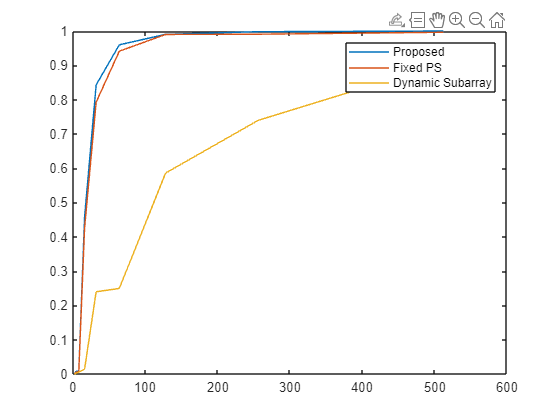

close all
M1 = squeeze(min(Compensated1));
M2 = squeeze(min(Compensated2));
M3 = squeeze(min(Compensated3));
plot(MSet,M1,MSet,M2,MSet,M3)
legend('Proposed','Fixed PS','Dynamic Subarray')

%%
set(0, 'defaultlinelinewidth', 1); set(0, 'defaultlinemarkersize', 8);
set(0, 'defaultaxesfontsize', 15); set(0, 'defaulttextfontsize', 15); 

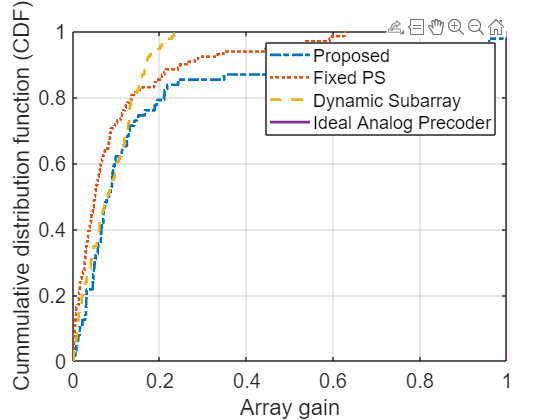

close all;
figure(1)
f1 = cdfplot(Compensated1(:,:,1));
set(f1,'LineWidth',2,'LineStyle','-.','Marker','none');
hold on
f2 = cdfplot(Compensated2(:,:,1));
set(f2,'LineWidth',2,'LineStyle',':','Marker','none');
hold on
f3 = cdfplot(Compensated3(:,:,1));
set(f3,'LineWidth',2,'LineStyle','--','Marker','none');
hold on
f4 = cdfplot(ones(Sysparam.K,1));
set(f4,'LineWidth',2,'LineStyle','-','Marker','none');
legend('Proposed','Fixed PS','Dynamic Subarray','Ideal Analog Precoder')
xlabel('Array gain')
ylabel('Cummulative distribution function (CDF)')
title('')

close all;
figure(2)
f1 = cdfplot(Compensated1(:,:,10));

Index in position 3 exceeds array bounds. Index must not exceed 9.

set(f1,'LineWidth',2,'LineStyle','-.','Marker','none');
hold on
f2 = cdfplot(Compensated2(:,:,10));
set(f2,'LineWidth',2,'LineStyle',':','Marker','none');
hold on
f3 = cdfplot(Compensated3(:,:,10));
set(f3,'LineWidth',2,'LineStyle','--','Marker','none');
hold on
f4 = cdfplot(ones(Sysparam.K,1));
set(f4,'LineWidth',2,'LineStyle','-','Marker','none');
legend('Proposed','Fixed PS','Dynamic Subarray','Ideal Analog Precoder')
xlabel('Array gain')
ylabel('Cummulative distribution function (CDF)')
title('')

close all;
figure(3)
f1 = cdfplot(Compensated1(:,:,11));
set(f1,'LineWidth',2,'LineStyle','-','Marker','none');
hold on
f2 = cdfplot(Compensated2(:,:,11));
set(f2,'LineWidth',2,'LineStyle','-.','Marker','none');
hold on
f3 = cdfplot(Compensated3(:,:,11));
set(f3,'LineWidth',2,'LineStyle','--','Marker','none');
hold on
f4 = cdfplot(ones(Sysparam.K,1));
set(f4,'LineWidth',2,'LineStyle',':','Marker','none');
legend('Proposed','Fixed PS','Dynamic Subarray','Ideal Analog Precoder')
xlabel('Array gain')
ylabel('Cummulative distribution function (CDF)')
title('')

